# Práctica 2. Filtros FIR e IIR

#### **Ejercicio 5**

El archivo mel2_note.wav contiene una melodía sobre la que se ha añadido una nota musical formada por varios armónicos. 

**a) **Carga y oye la señal. Representa la señal en el dominio de la frecuencia. 

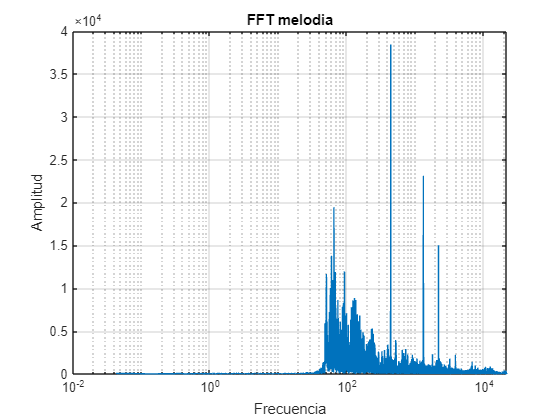

load('datos_melodia.mat')

t=0:1/fs:23-1/fs;

n=length(data);
frec=linspace(0,fs/2,n/2+1);

fft_mel=abs(fft(data));
fft_mel=fft_mel(1:length(frec));%Nos quedamos solo con los datos de frecuencia positivos 
figure(1)
semilogx(frec,fft_mel);
ylabel('Amplitud')
xlabel('Frecuencia')
title('FFT melodia');
grid;

sound(data,fs);

**b) **Diseña filtros IIR apropiados para eliminar el pitido en la señal, y representa su respuesta en frecuencia.

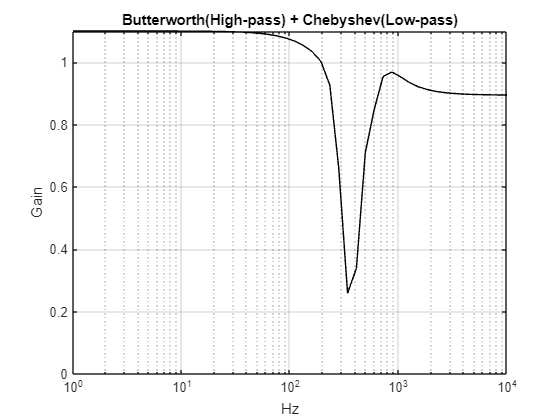

f_pass = 0.8*440;
n=4;
[b, a]=cheby2 (n, 20, f_pass/fs*2,"low");
[bh,ah] = ellip(n,2,20,f_pass*2/fs*1.2,"high");
%[b, a] = butter(n, f_pass / (fs / 2), 'low'); % Filtro pasa bajo
f=logspace (0,4);
% Respuesta en frecuencia del filtro
gl=freqz(b, a, f, fs);
gh =freqz(bh, ah, f, fs);
g=gl+gh;
semilogx (f, abs (g),'k'); %plots linear amplitude 
axis ([1 10000 0 1.1]); grid;
ylabel('Gain'); xlabel('Hz'); title ('Butterworth(High-pass) + Chebyshev(Low-pass)');

**c) **Filtra la señal y compara el resultado con la señal original. Para ello, oye la señal filtrada y represéntala en el dominio de la frecuencia. 

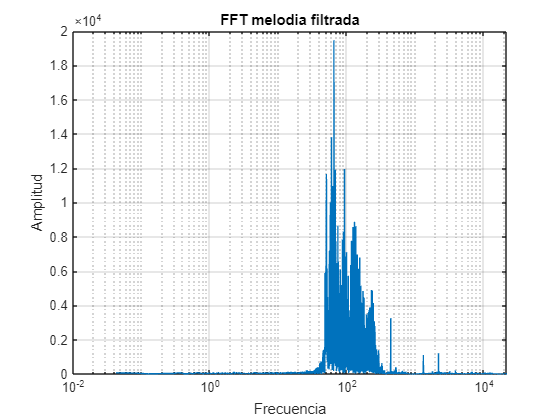

data_filt = filter(b, a, data);
fft_mel_filt=abs(fft(data_filt));
fft_mel_filt=fft_mel_filt(1:length(frec));%Nos quedamos solo con los datos de frecuencia positivos 
figure(2)
semilogx(frec,fft_mel_filt);
ylabel('Amplitud')
xlabel('Frecuencia')
title('FFT melodia filtrada');
grid;

sound(data_filt,fs);